**Green function** 


$$s\left(t\right)*G\left(x,z,t,0,z_s ,0\right)=-\sum_{j=-\infty }^{\infty } \frac{\epsilon_j }{4\pi r_j }s\left(t-\frac{r_j }{c}\right)$$


$s\left(t\right)$ is the transmitter function

Ex. $s\left(t\right)=\frac{\sin \left(\pi \textrm{Bt}\right)}{\pi \textrm{Bt}}$

rho = 1000

rho = 1000

c = 1470

c = 1470


% transmitter function 
B = 500

B = 500

dt = 1/(2*B)

dt = 1.0000e-03

start = -0.05

start = -0.0500

finish = 0.05

finish = 0.0500


t = linspace(start,finish,(finish-start)/dt)

t =    -0.0500   -0.0490   -0.0480   -0.0470   -0.0460   -0.0449   -0.0439   -0.0429   -0.0419   -0.0409   -0.0399   -0.0389   -0.0379   -0.0369   -0.0359   -0.0348   -0.0338   -0.0328   -0.0318   -0.0308   -0.0298   -0.0288   -0.0278   -0.0268   -0.0258   -0.0247   -0.0237   -0.0227   -0.0217   -0.0207   -0.0197   -0.0187   -0.0177   -0.0167   -0.0157   -0.0146   -0.0136   -0.0126   -0.0116   -0.0106   -0.0096   -0.0086   -0.0076   -0.0066   -0.0056   -0.0045   -0.0035   -0.0025   -0.0015   -0.0005


s = @(t)awgn(sinc(B*t),100)

s = function_handle with value:
    @(t)awgn(sinc(B*t),100)


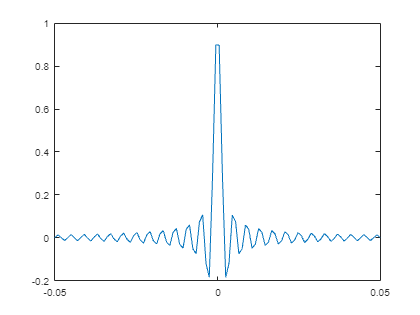


plot(t,s(t))

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% depth
h = 350;

% transmitter
x_s = 0;
z_s = 100;

% receiver 
x = 1000;
z = 120;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
start = -1;
finish = 4;

t = linspace(start,finish,(finish-start)/dt);
z_list = linspace(0, h, 10)

z_list =          0   38.8889   77.7778  116.6667  155.5556  194.4444  233.3333  272.2222  311.1111  350.0000


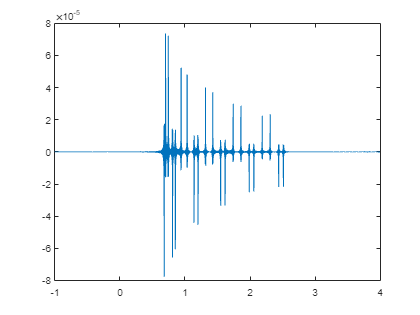

s_table = zeros(size(z_list, 1), size(t,2));

for i = 1:size(z_list,2)
    s_table(i,:) = greenFunc(x_s,z_s,x,z_list(i),h,c,s,t);
end

plot(t, s_table(end/2,:))


%% check on only one receiver 
s = flip(s_table(end/2,:))

s = 1.0e-04 *

    0.0004    0.0001   -0.0004   -0.0002    0.0004    0.0002   -0.0003   -0.0001    0.0004    0.0002   -0.0004   -0.0001    0.0004    0.0002   -0.0004   -0.0002    0.0003    0.0001   -0.0003   -0.0002    0.0004    0.0001   -0.0004   -0.0002    0.0004    0.0001   -0.0004   -0.0001    0.0004    0.0001   -0.0003   -0.0002    0.0004    0.0002   -0.0004   -0.0002    0.0003    0.0002   -0.0004   -0.0001    0.0003    0.0002   -0.0004   -0.0002    0.0004    0.0001   -0.0004   -0.0002    0.0004    0.0002


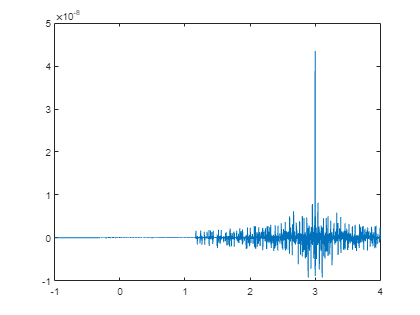

plot(t, greenFunc2(x,z_list(end/2),x_s,z_s,h,c,s,t,dt))

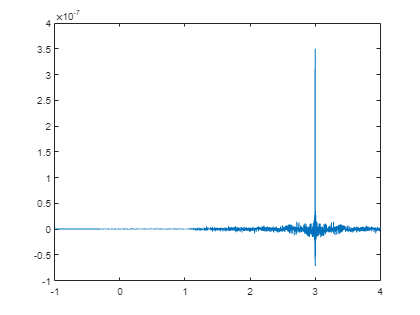

%%

out = zeros(1,size(s_table,2));
for i = 1:size(z_list,2)
    out = out + greenFunc2(x,z_list(i),x_s,z_s,h,c,flip(s_table(i,:)),t,dt);
end
plot(t,out)

Plot energy 

ds = 2

ds = 2

wx = 50

wx = 50

wz = 50

wz = 50


x_s

x_s = 0

z_s

z_s = 100

[X,Z] = meshgrid(x_s-wx/2:ds:x_s+wx/2, z_s-wz/2:ds:z_s+wz/2);
Z

Z =     75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75    75
    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77    77
    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79    79
    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81    81
    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83    83
    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85    85
    87    87    87    87    87    87    87    87    87

X

X =    -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9    -7    -5    -3    -1     1     3     5     7     9    11    13    15    17    19    21    23    25
   -25   -23   -21   -19   -17   -15   -13   -11    -9


Energy = zeros(size(X));
for i = 1:size(Z,1)
    for j = 1:size(X,2)
        out = zeros(1,size(s_table,2));
        for k = 1:size(z_list,2)
            out = out + greenFunc2(x,z_list(k),X(1,j),Z(i,1),h,c,flip(s_table(k,:)),t,dt);
        end
        Energy(i,j) = sum(out.^2);
    end
end
Energy

Energy = 1.0e-12 *

    0.0579    0.0578    0.0568    0.0557    0.0552    0.0548    0.0531    0.0501    0.0475    0.0470    0.0477    0.0477    0.0465    0.0457    0.0470    0.0494    0.0507    0.0502    0.0500    0.0520    0.0557    0.0590    0.0607    0.0612    0.0616    0.0622
    0.0663    0.0681    0.0684    0.0664    0.0629    0.0597    0.0579    0.0572    0.0563    0.0545    0.0522    0.0508    0.0510    0.0522    0.0531    0.0531    0.0531    0.0547    0.0581    0.0623    0.0655    0.0673    0.0680    0.0682    0.0682    0.0682
    0.0661    0.0676    0.0689    0.0687    0.0663    0.0622    0.0585    0.0563    0.0552    0.0539    0.0525    0.0520    0.0526    0.0528    0.0518    0.0505    0.0511    0.0543    0.0589    0.0627    0.0652    0.0668    0.0684    0.0698    0.0703    0.0700
    0.0605    0.0616    0.0633    0.0652    0.0663    0.0651    0.0614    0.0566    0.0530    0.0518    0.0523    0.0527    0.0520    0.0509    0.0509    0.0526    0.0555    0.0583    0.0609    0.0

ds_fine = 0.01

ds_fine = 0.0100

linspace(1,size(X2,2),size(X,2))

Unrecognized function or variable 'X2'.

1:size(X,2)
[X2,Z2] = meshgrid(x_s-wx/2:ds_fine:x_s+wx/2, z_s-wz/2:ds_fine:z_s+wz/2);
outData = interp2(X, Z, Energy, X2, Z2, 'linear');
imagesc(outData);
set(gca, 'XTickLabel', X(1,:));
set(gca, 'YTickLabel', Z(:,1));
colorbar;

function s_conv = greenFunc(x_s, z_s, x, z, h, c, s, t)
    s_conv = zeros(size(t));
    n_ray = 10;
    for j = -n_ray:n_ray
        if mod(j,2) == 0
            % if even 
            r_j = sqrt((x-x_s)^2 + (z-z_s+j*h)^2);
            eps_j = 1;
        else
            % if odds
            r_j = sqrt((x-x_s)^2 + (z+z_s-(j+1)*h)^2);
            eps_j = -1;
        end
%         s_conv = s_conv - (eps_j/(4*pi*r_j))*delayseq(s(t)', r_j/c, dt)';
        s_conv = s_conv - (eps_j/(4*pi*r_j))*s(t-r_j/c);
    end
end

function s_conv = greenFunc2(x_s, z_s, x, z, h, c, s, t, dt)
    s_conv = zeros(size(t));
    n_ray = 10;
    for j = -n_ray:n_ray
        if mod(j,2) == 0
            % if even 
            r_j = sqrt((x-x_s)^2 + (z-z_s+j*h)^2);
            eps_j = 1;
        else
            % if odds
            r_j = sqrt((x-x_s)^2 + (z+z_s-(j+1)*h)^2);
            eps_j = -1;
        end
        s_conv = s_conv - (eps_j/(4*pi*r_j))*delayseq(s', r_j/c, 1/dt)';
    end
end